clear; close all;

What's new? This script uses sim_loc_conf_unity_resp_EVResp.m which is new. This function always assumes the estimation is at the model averaging locaiton, that is the weighted average of the modes of the two posteriors from the two causal scenarios. 

% However, because we introduced the new paradigm where subjects report 
% confidence by binary choices, it doesn't matter where they estimate the 
% stimulus location, because we are assuming the confidence binary decision
% is made by comparing the variance of the posterior they chose to a 
% criterion. All of this can be accomplished by the function ending in 
% EVResp, and can be visualized in this script.

## out dir

cur_dir                          = pwd;
[project_dir, ~]                 = fileparts(cur_dir);
out_dir                          = fullfile(cur_dir, 's1Fig');
if ~exist(out_dir,'dir') mkdir(out_dir); end

## experimental info

% fix parameters for the experiment info
speaker_span       = 65.5 * 2; % cm
sitting_dist       = 113; % cm
screen_width       = 170; % cm
screenX            = 1024; % pixel
screenXdeg         = rad2deg(atan(screen_width / 2 / sitting_dist)) .* 2;
screen_mid         = screenX ./2;
num_speaker_int    = 15; % 15 intervals between 16 speakers
cm_per_aud_ind     = speaker_span / num_speaker_int;
pixel_per_cm       = screenX / screen_width;
aud_level          = [6 8 9 11];
aud_VA             = -30:4:30;
deg_per_px         = screenXdeg / screenX;

fixP.screenX       = screenXdeg;
fixP.x             = -screenXdeg /2 : deg_per_px : screenXdeg/2; % the screen deg space
center_x           = 0;

sA                 = aud_VA(aud_level); % in deg. 8.5 being middle point
sV                 = sA;
aA                 = 1;
sAV                = combvec(sA, sV);
num_s              = size(sAV,2); % number of conditions

% fix parameters for the cost function
% fixP.maxPoint     = 1;
% fixP.minPoint     = 0.01;
% fixP.elbow        = 1000; % 1/4 of ScreenX is what we are using right now

% experimental info for analysis and plot
aud_locs          = sA;
vis_locs          = sV;
diffs             = zeros(length(aud_locs), length(vis_locs));
for i = 1:length(aud_locs)
    for j = 1:length(vis_locs)
        diffs(i, j) = aud_locs(i) - vis_locs(j);
    end
end
disc_locs   = unique(abs(diffs));

## free parameters

bA                 = 0;
sigA               = 4.5;
sigVs              = [1,5];
muP                = 0;
sigP               = 10000; % arbitarily using screen width here
pCommon            = 0.57; % only 1/4 of the trials are common cause so I assume this here
criterion = [5,5;3.2,5;4.5,17]; % eyeballed arbitary criterion 
% derivative info
num_rep            = 100;
ds_loc             = {'Model averaging E[V]','Model averaging MAP', 'Model selection','Probability Matching'};
ds_conf            = {'M1','M2','M3'};
cue_label   = {'Post-cue: A','Post-cue: V'};
num_cue            = numel(cue_label);
rel_label   = {'High reliability','Low reliability'};

## simulate data

loc                = NaN(num_s,numel(ds_loc), num_cue, numel(sigVs), num_rep);
% num_s: stimulus location combination
% 3 decision strategies
% 2 modalities(1 = aud, 2 = vis)
% 2 visual reliabilities
% num_rep
variance           = NaN(num_s,numel(ds_conf), num_cue, numel(sigVs), num_rep);
unity              = NaN(num_s, numel(sigVs), num_rep);
p_conf             = NaN(num_s,numel(ds_conf), num_cue, numel(sigVs)); % this is summed per condition so just one less dimension
for i = 1:num_s
    for v = 1:numel(sigVs)
        [loc(i,:,:,v,:), unity(i,v,:), pdf(i,v), variance(i,:,:,v,:), p_conf(i,:,:,v)] = sim_loc_conf_unity_resp_EVResp(pCommon, num_rep, sAV(1,i),...
            sAV(2,i), aA, bA, sigA, sigVs(v), muP, sigP, fixP, criterion);
    end
end



## Plot set up

lw = 2;
fontSZ = 15;
titleSZ = 20;
dotSZ = 80;
clt = [30, 120, 180; % blue
    227, 27, 27;  % dark red
    128, 128, 128]./255; % light red

## analyze data

allDiffs = unique(abs(sA' - sV));
num_diff = numel(allDiffs);

org_resp = NaN(numel(ds_loc),numel(sA), numel(sV), num_cue, numel(sigVs), num_rep);
% org_conf = NaN(numel(ds_conf),numel(sA), numel(sV), num_cue, numel(sigVs), num_rep);
[mean_conf, sd_conf, nT_conf] = deal(NaN(numel(ds_conf),num_diff, num_cue, numel(sigVs)));

for d = 1:numel(ds_conf)

    % organize data

    if d == numel(ds_conf)
        d_loc = 3;
    else
        d_loc = d;
    end

    d_resp = squeeze(loc(:,d_loc,:,:,:));
    org_resp(d_loc,:,:,:,:,:) = reshape(d_resp, [numel(sA), numel(sV), num_cue, numel(sigVs), num_rep]);

    % d_conf = squeeze(conf(:,d,:,:,:));
    % org_conf(d,:,:,:,:,:) = reshape(d_conf, [numel(sA), numel(sV), num_cue, numel(sigVs), num_rep]);

    d_var = squeeze(variance(:,d,:,:,:));
    org_var(d,:,:,:,:,:) = reshape(d_var, [numel(sA), numel(sV), num_cue, numel(sigVs), num_rep]);

    d_p_conf = squeeze(p_conf(:,d,:,:));
    org_p_conf(d,:,:,:,:) = reshape(d_p_conf, [numel(sA), numel(sV), num_cue, numel(sigVs)]);

    % organize response by discrepancy

    for i = 1:length(allDiffs)

        diff = allDiffs(i);

        % Find pairs of audIdx and visIdx that match this difference
        [audPairs, visPairs] = find(abs(sA' - sV) == diff);
        % tempData_conf = [];
        tempData_var = [];
        tempData_p_conf = [];
        % For each pair, extract and store the corresponding data
        for j = 1:numel(audPairs)
            % Extract data for this specific audIdx and visIdx pair across all other dimensions
            % tempData_conf = cat(3, tempData_conf, squeeze(org_conf(d, audPairs(j), visPairs(j), :, :,:)));
            tempData_var = cat(3, tempData_var, squeeze(org_var(d, audPairs(j), visPairs(j), :, :,:)));
            tempData_p_conf = cat(3, tempData_p_conf, squeeze(org_p_conf(d, audPairs(j), visPairs(j), :, :)));
        end

        % store conf by discrepancy
        % diff_conf{d,i} = tempData_conf;
        diff_var{d,i} = tempData_var;
        diff_p_conf{d,i} = tempData_p_conf;
        % take average and sd
        % mean_conf(d,i,:,:) = squeeze(mean(tempData_conf,3));
        % sd_conf(d,i,:,:) = squeeze(std(tempData_conf,[],3));
        mean_var(d,i,:,:) = squeeze(mean(tempData_var,3));
        sd_var(d,i,:,:) = squeeze(std(tempData_var,[],3));
        mean_p_conf(d,i,:,:) = squeeze(mean(tempData_p_conf,3));
        sd_p_conf(d,i,:,:) = squeeze(std(tempData_p_conf,[],3));
        % nT_conf(d,i,:,:) = repmat(squeeze(size(tempData,3)),num_cue, numel(sigVs));
    end

end

## plot confidence/variance/p(report Confident) as a function of discrepancy and reliability

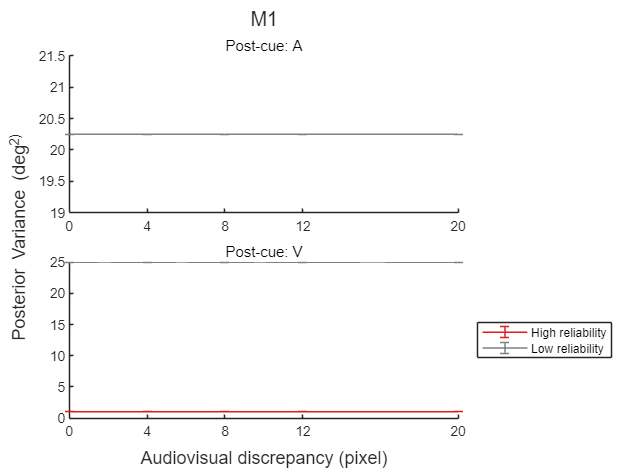

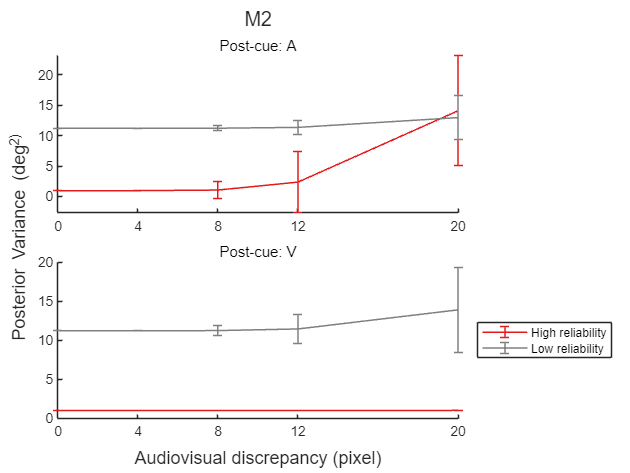

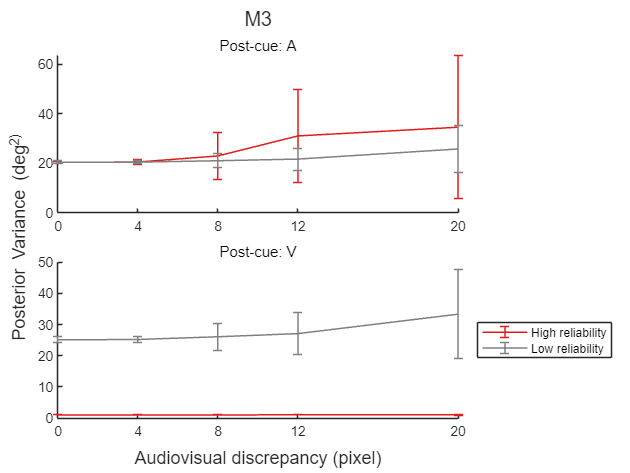

indVar = "v"; 
% use this to choose which independent variable you compare between conditions
% choices are c:confidence, v:variance, and p:p(report confident)
switch indVar
    % case "c"
    % mean_iv = mean_conf;
    % sd_iv = sd_conf;
    % indVarName = "Confidence Radius (cm)";
    case "v"
    mean_iv = mean_var;
    sd_iv = sd_var;
    indVarName = "Posterior Variance (deg^2)";
    case "p"
    mean_iv = 1-mean_p_conf;
    sd_iv = sd_p_conf;
    indVarName = "P(report Confident)";
end

for d = 1:numel(ds_conf)

    figure; hold on

    t = tiledlayout(2, 1);
    title(t, ds_conf{d})
    xlabel(t, 'Audiovisual discrepancy (pixel)');
    ylabel(t, indVarName);
    t.TileSpacing = 'compact';
    t.Padding = 'compact';

    for cue = 1:num_cue
        nexttile
        title(cue_label{cue})
        hold on
        for rel = 1:numel(sigVs)
            if indVar == "p"
                plot(disc_locs, squeeze(mean_iv(d,:,cue,rel)),'-o','Color',clt(rel+1,:),'LineWidth',1)
            else
            errorbar(disc_locs, squeeze(mean_iv(d,:,cue,rel)), ...
                squeeze(sd_iv(d,:,cue,rel)),'Color',clt(rel+1,:),'LineWidth',1)
            end
        end
        xticks(disc_locs)
    end
    legend(rel_label, 'Location', 'eastoutside');

    saveas(gca, fullfile(out_dir, sprintf('conf_%s',  ds_conf{d})), 'png')

end